%contour of iteration
x=-5:0.005:5;
y=-5:0.005:5;
[X,Y]=meshgrid(x,y);
F=(X.^2+Y-11).^2+(X+Y.^2-7).^2;
v=[-2:2:10 10:10:100 100:20:200]

v =     -2     0     2     4     6     8    10    10    20    30    40    50    60    70    80    90   100   100   120   140   160   180   200


[c,h]=contour(X,Y,F,v,'linewidth',2)

c = 	1.0e+04 *

    0.0002   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
    0.0333   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   

h =   Contour - 属性:

    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 2
         Fill: 'off'
    LevelList: [-2 0 2 4 6 8 10 20 30 40 50 60 70 80 90 100 120 140 160 180 200]
        XData: [2001×2001 double]
        YData: [2001×2001 double]
        ZData: [2001×2001 double]

  显示 所有属性


colorbar


yc1=(x+2).^2;
%yc2=(4*x)/10;
hold on

x1=ceil((-sqrt(5)-2)*100)/100

x1 = -4.2300

x2=floor((sqrt(5)-2)*100)/100

x2 = 0.2300

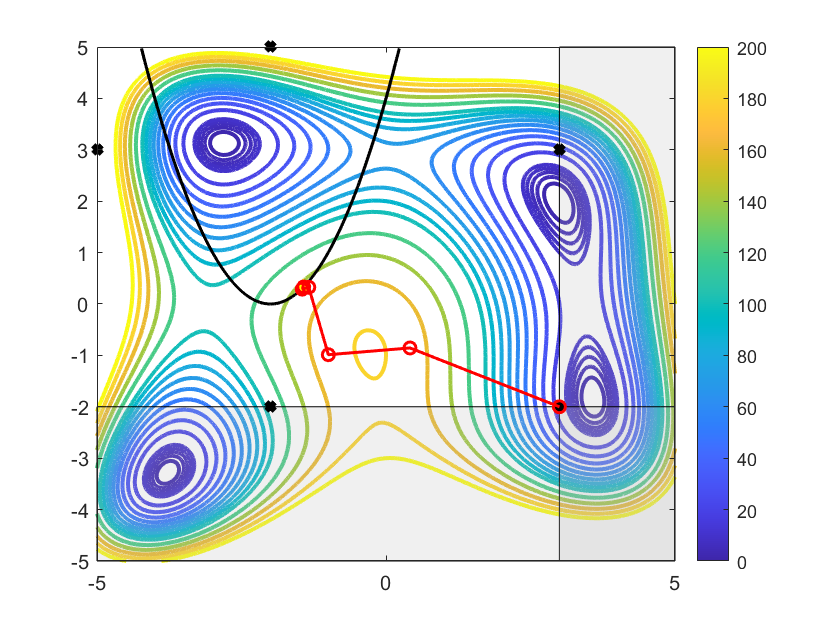

x_cut=x1:0.005:x2;
y_cut=(x_cut+2).^2;
plot(x_cut,y_cut,"black","linewidth",1.5)
fill([3 3 5 5],[-5 5 5 -5],[0.7 0.7 0.7],'facealpha',0.2)
fill([-5 5 5 -5],[-2 -2 -5 -5],[0.7 0.7 0.7],'facealpha',0.2)

scatter(-3.6546,2.7377,"yellow","filled","d","linewidth",1.5)%minimum point
scatter(-0.2983,2.8956,"yellow","filled","d","linewidth",1.5)%sub-minimum point
scatter(-1.4242,0.3315,"yellow","filled","d","linewidth",1.5)%sub-minimum point
scatter(-2.8051,3.2832,"green","x","linewidth",1.5)%global minimum point
scatter([-5 -2 3 -2 3],[3 -2 3 5 -2],"black","x","linewidth",3)
%plot(xc1,xc2,"-or","linewidth",1.5)%for fmincon
%plot(xa1,xa2,"-or","linewidth",1.5)%for fmincon
%plot(xb1,xb2,"-oc","linewidth",1.5)%for fmincon
%plot(xd1,xd2,"-om","linewidth",1.5)%for fmincon
%plot(xe1,xe2,"-om","linewidth",1.5)%for fmincon
plot(output.xarray(1,:),output.xarray(2,:),"-or","linewidth",1.5)%for implementation
xlim([-5,5])
ylim([-5,5])
hold off